# Graph Theory and Water Networks

Load library paths

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## Network properties

## Simple graphs

In its basic form, a water distribution network can be described as a graph composed of nodes and links.

% create the adjacency matrix
A1 = [0 1 0 0 0 0
     1 0 1 0 0 0
     0 1 0 1 1 0
     0 0 1 0 0 1
     0 0 1 0 0 1
     0 0 0 1 1 0]

A1 =      0     1     0     0     0     0
     1     0     1     0     0     0
     0     1     0     1     1     0
     0     0     1     0     0     1
     0     0     1     0     0     1
     0     0     0     1     1     0


G1 = graph(A1)

G1 =   graph with properties:

    Edges: [6×2 table]
    Nodes: [6×0 table]


G1.Edges.Weight = [500, 3200, 1600, 1600, 1600, 1600]';
G1.Nodes.Name =  {'n1' 'n2' 'n3' 'n4' 'n5' 'n6' }'

G1 =   graph with properties:

    Edges: [6×2 table]
    Nodes: [6×1 table]


E1 = G1.Edges

E1 = 6×2 table
        EndNodes        Weight
    ________________    ______

    {'n1'}    {'n2'}      500 
    {'n2'}    {'n3'}     3200 
    {'n3'}    {'n4'}     1600 
    {'n3'}    {'n5'}     1600 
    {'n4'}    {'n6'}     1600 
    {'n5'}    {'n6'}     1600 


N1 = G1.Nodes

N1 = 6×1 table
     Name 
    ______

    {'n1'}
    {'n2'}
    {'n3'}
    {'n4'}
    {'n5'}
    {'n6'}


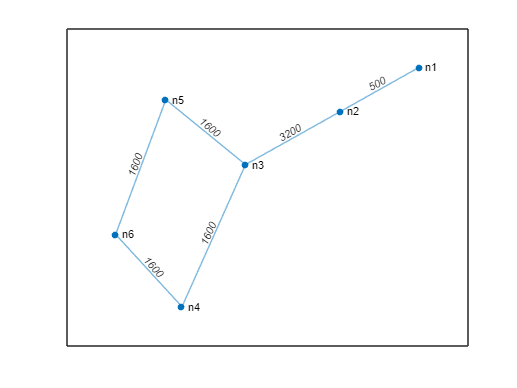

figure
plot(G1,'EdgeLabel',G1.Edges.Weight)

## Directed graphs

When we have information regarding the flows, we can plot the directed graph (***digraph***)

% create the adjacency matrix
A2 = [0 1 0 0 0 0
     0 0 1 0 0 0
     0 0 0 1 1 0
     0 0 0 0 0 1
     0 0 0 0 0 1
     0 0 0 0 0 0]

A2 =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     1     0
     0     0     0     0     0     1
     0     0     0     0     0     1
     0     0     0     0     0     0


G2 = digraph(A2)

G2 =   digraph with properties:

    Edges: [6×2 table]
    Nodes: [6×0 table]


G2.Edges.Weight = [500, 3200, 1600, 1600, 1600, 1600]';
G2.Nodes.Name =  {'n1' 'n2' 'n3' 'n4' 'n5' 'n6' }'

G2 =   digraph with properties:

    Edges: [6×2 table]
    Nodes: [6×1 table]


E2 = G2.Edges

E2 = 6×2 table
        EndNodes        Weight
    ________________    ______

    {'n1'}    {'n2'}      500 
    {'n2'}    {'n3'}     3200 
    {'n3'}    {'n4'}     1600 
    {'n3'}    {'n5'}     1600 
    {'n4'}    {'n6'}     1600 
    {'n5'}    {'n6'}     1600 


N2 = G2.Nodes

N2 = 6×1 table
     Name 
    ______

    {'n1'}
    {'n2'}
    {'n3'}
    {'n4'}
    {'n5'}
    {'n6'}


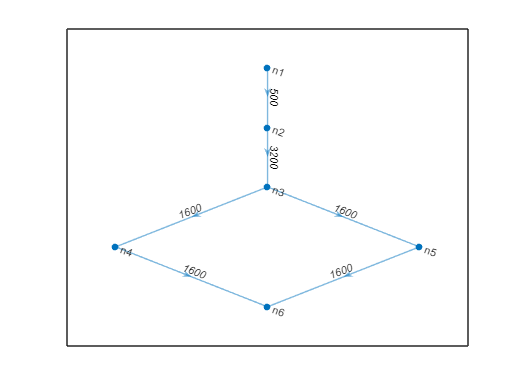

figure
plot(G2,'EdgeLabel',G2.Edges.Weight)

We can use this basic structure to compute some graph theoretic metrics

## Graphs of water systems

%% Get data from L-Town benchmark
g = epanet('l-town.inp');

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "l-town.inp"...
Input File "l-town.inp" loaded successfully.


A = g.getConnectivityMatrix;
C = g.getNodeCoordinates;
L = g.getLinkLength;
D = g.getLinkDiameter;
E = g.getNodeElevations;
NIP = g.getNodeNameID

NIP = 1×785 cell array
    {'n1'}    {'n2'}    {'n3'}    {'n4'}    {'n5'}    {'n6'}    {'n7'}    {'n8'}    {'n9'}    {'n10'}    {'n11'}    {'n12'}    {'n13'}    {'n14'}    {'n15'}    {'n16'}    {'n17'}    {'n18'}    {'n19'}    {'n20'}    {'n21'}    {'n22'}    {'n23'}    {'n24'}    {'n25'}    {'n26'}    {'n27'}    {'n28'}    {'n29'}    {'n30'}    {'n31'}    {'n32'}    {'n33'}    {'n34'}    {'n35'}    {'n36'}    {'n37'}    {'n38'}    {'n39'}    {'n40'}    {'n41'}    {'n42'}    {'n43'}    {'n44'}    {'n45'}    {'n46'}    {'n47'}    {'n48'}    {'n49'}    {'n50'}    {'n51'}    {'n52'}    {'n53'}    {'n54'}    {'n55'}    {'n56'}    {'n57'}    {'n58'}    {'n59'}    {'n60'}    {'n61'}    {'n62'}    {'n63'}    {'n64'}    {'n65'}    {'n66'}    {'n67'}    {'n68'}    {'n69'}    {'n70'}    {'n71'}    {'n72'}    {'n73'}    {'n74'}    {'n75'}    {'n76'}    {'n77'}    {'n78'}    {'n79'}    {'n80'}    {'n81'}    {'n82'}    {'n83'}    {'n84'}    {'n85'}    {'n86'}    {'n87'}    {'n88'}    {'n89'}    {'n

EIP = g.getLinkNameID

EIP = 1×909 cell array
  Columns 1 through 842

    {'p1'}    {'p2'}    {'p3'}    {'p4'}    {'p5'}    {'p6'}    {'p7'}    {'p8'}    {'p9'}    {'p10'}    {'p11'}    {'p12'}    {'p13'}    {'p14'}    {'p15'}    {'p16'}    {'p17'}    {'p18'}    {'p19'}    {'p20'}    {'p21'}    {'p22'}    {'p23'}    {'p24'}    {'p25'}    {'p26'}    {'p27'}    {'p28'}    {'p29'}    {'p30'}    {'p31'}    {'p32'}    {'p33'}    {'p34'}    {'p35'}    {'p36'}    {'p37'}    {'p38'}    {'p39'}    {'p40'}    {'p41'}    {'p42'}    {'p43'}    {'p44'}    {'p45'}    {'p46'}    {'p47'}    {'p48'}    {'p49'}    {'p50'}    {'p51'}    {'p52'}    {'p53'}    {'p54'}    {'p55'}    {'p56'}    {'p57'}    {'p58'}    {'p59'}    {'p60'}    {'p61'}    {'p62'}    {'p63'}    {'p64'}    {'p65'}    {'p66'}    {'p67'}    {'p68'}    {'p69'}    {'p70'}    {'p71'}    {'p72'}    {'p73'}    {'p74'}    {'p75'}    {'p76'}    {'p77'}    {'p78'}    {'p79'}    {'p80'}    {'p81'}    {'p82'}    {'p83'}    {'p84'}    {'p85'}    {'p86'}    {'p87'}    


%% Create graph G
G = graph(A);
G.Edges.Length = L'

G =   graph with properties:

    Edges: [909×3 table]
    Nodes: [785×0 table]


G.Edges.Diameter = D';
G.Nodes.Elevation = E';
G.Nodes.Name = NIP';
G.Edges.Name = EIP';

% Plot 2D network graph with heatmap the elevations
figure
p1 = plot(G,'XData',C{1},'YData',C{2})

p1 =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [138.2200 274.2300 271.2800 186.6200 158.9300 261.3300 369.9700 162.6500 256.5400 361.4500 167.1400 271.0900 170.6800 302.2400 344.8400 336.3700 177.1200 331.1600 439.9100 325.7800 181.2200 525.8300 314.6600 393.3000 195.9500 309.6600 … ]
         YData: [1.5496e+03 1.5046e+03 1.4810e+03 1.3267e+03 1.2333e+03 1.3620e+03 1.5433e+03 1.1813e+03 1.3188e+03 1.4754e+03 1.1186e+03 1.2813e+03 1.0598e+03 1.2793e+03 1.3474e+03 1.2771e+03 987.9800 1.2272e+03 1.3911e+03 1.1732e+03 914.6700 … ]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

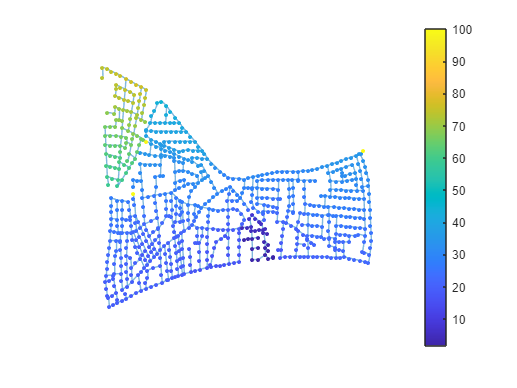

G.Nodes.NodeColors = E';
p1.NodeCData = G.Nodes.NodeColors;
colorbar
set(gca,'visible','off')


% Plot 3D network graph with heatmap the elevations
figure
p2 = plot(G,'XData',C{1},'YData',C{2},'ZData',E)

p2 =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [138.2200 274.2300 271.2800 186.6200 158.9300 261.3300 369.9700 162.6500 256.5400 361.4500 167.1400 271.0900 170.6800 302.2400 344.8400 336.3700 177.1200 331.1600 439.9100 325.7800 181.2200 525.8300 314.6600 393.3000 195.9500 309.6600 … ]
         YData: [1.5496e+03 1.5046e+03 1.4810e+03 1.3267e+03 1.2333e+03 1.3620e+03 1.5433e+03 1.1813e+03 1.3188e+03 1.4754e+03 1.1186e+03 1.2813e+03 1.0598e+03 1.2793e+03 1.3474e+03 1.2771e+03 987.9800 1.2272e+03 1.3911e+03 1.1732e+03 914.6700 … ]
         ZData: [73.2105 73.8737 73.1782 68.2608 65.5695 70.9095 75.9175 64.4833 69.2626 74.3469 63.0588 68.2274 61.9901 68.5805 70.9492 68.7986 60.5935 67.1420 73.3626 65.9549 

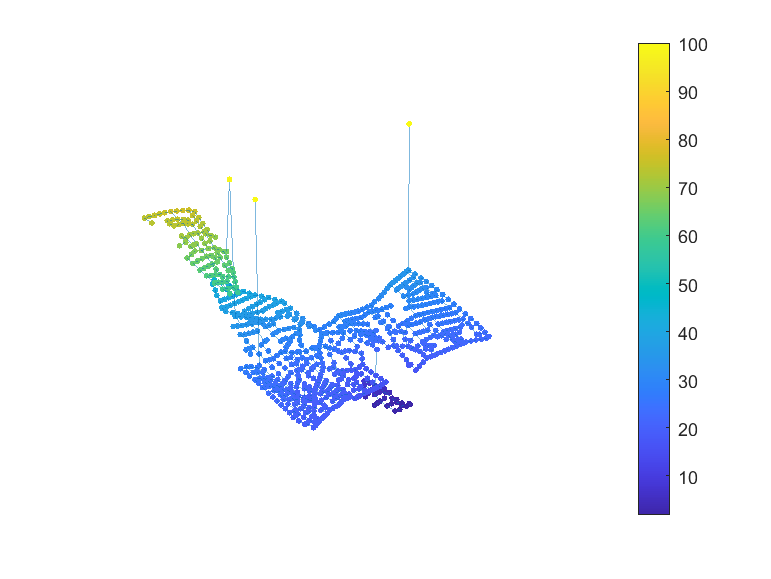

G.Nodes.NodeColors = E';
p2.NodeCData = G.Nodes.NodeColors;
grid on
colorbar
set(gca,'visible','off')

## Algorithms using directed graphs

## Tree search algorithms

Useful if you want to find which nodes are affected downstream.

%% Get data from Net1 benchmark
g = epanet('net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "net1.inp"...
Input File "net1.inp" loaded successfully.


Nnode = g.getNodeCount

Nnode = int32
11

A = zeros(Nnode);
C = g.getNodeCoordinates;
L = g.getLinkLength;
D = g.getLinkDiameter;
E = g.getNodeElevations;
NIP = g.getNodeNameID

NIP = 1×11 cell array
    {'10'}    {'11'}    {'12'}    {'13'}    {'21'}    {'22'}    {'23'}    {'31'}    {'32'}    {'9'}    {'2'}


EIP = g.getLinkNameID

EIP = 1×13 cell array
    {'10'}    {'11'}    {'12'}    {'21'}    {'22'}    {'31'}    {'110'}    {'111'}    {'112'}    {'113'}    {'121'}    {'122'}    {'9'}



%% Compute the mean flow
Fmean = mean(g.getComputedHydraulicTimeSeries.Flow,1);

%% Compute the new adjacency matrix based on the mean flow in the network
Fsign = sign(Fmean);
Nidx = g.getLinkNodesIndex;
for i = 1:size(Nidx,1)
    if Fsign(i) == 1
        A(Nidx(i,1),Nidx(i,2)) = 1;
    else 
        A(Nidx(i,2),Nidx(i,1)) = 1;
    end
end

G1 = graph(g.getConnectivityMatrix);

G2 = digraph(A);
G2.Nodes.Name = NIP';
G2.Edges.Name = EIP';

p = plot(G2,'XData',C{1},'YData',C{2},'EdgeLabel', round(Fmean,1));
set(gca,'visible','off')

Find all downstream nodes starting from Node '12' (vertex 3) using a breadth-first search

downStreamNodes = bfsearch(G2,'12')

downStreamNodes = 5×1 cell array
    {'12'}
    {'13'}
    {'22'}
    {'23'}
    {'32'}


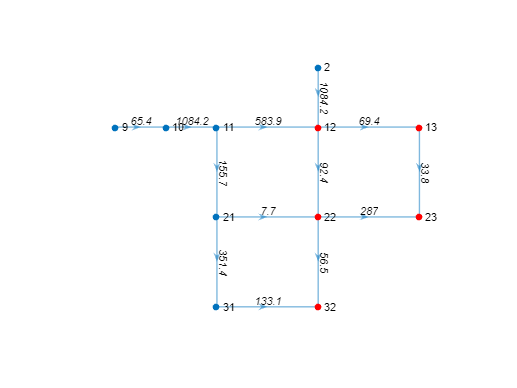

highlight(p,downStreamNodes,'NodeColor','r')


downStreamNodesBF = bfsearch(G2,'12')

downStreamNodesBF = 5×1 cell array
    {'12'}
    {'13'}
    {'22'}
    {'23'}
    {'32'}


downStreamNodesDF = dfsearch(G2,'12')

downStreamNodesDF = 5×1 cell array
    {'12'}
    {'13'}
    {'23'}
    {'22'}
    {'32'}



% MATLAB R2021a - allpaths
allpath = allpaths(G2,'11','32','MaxNumPaths',5) % Find all paths between two nodes

allpath = 3×1 cell array
    {1×4 cell}
    {1×4 cell}
    {1×4 cell}


allpath{:}

ans = 1×4 cell array
    {'11'}    {'12'}    {'22'}    {'32'}


ans = 1×4 cell array
    {'11'}    {'21'}    {'22'}    {'32'}


ans = 1×4 cell array
    {'11'}    {'21'}    {'31'}    {'32'}



allcyc = allcycles(G1)

allcyc = 6×1 cell array
    {[    2 3 4 7 6 5]}
    {[2 3 4 7 6 9 8 5]}
    {[        2 3 6 5]}
    {[    2 3 6 9 8 5]}
    {[        3 4 7 6]}
    {[        5 6 9 8]}


***Question****: How can we find from which nodes a contaminant may have originated?*

***Question****: What are the drawbacks of using the average flow?*

## Compute shortest path

Useful when you want to find when a contaminant will reach a certain node. 

%% Get data from Hanoi benchmark
g = epanet('hanoi-3.inp');

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "hanoi-3.inp"...
Input File "hanoi-3.inp" loaded successfully.


Nnode = g.getNodeCount

Nnode = int32
32

A = zeros(Nnode);
C = g.getNodeCoordinates;
L = g.getLinkLength;
D = g.getLinkDiameter;
E = g.getNodeElevations;
NIP = g.getNodeNameID

NIP = 1×32 cell array
    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'10'}    {'11'}    {'12'}    {'13'}    {'14'}    {'15'}    {'16'}    {'17'}    {'18'}    {'19'}    {'20'}    {'21'}    {'22'}    {'23'}    {'24'}    {'25'}    {'26'}    {'27'}    {'28'}    {'29'}    {'30'}    {'31'}    {'32'}    {'1'}


EIP = g.getLinkNameID

EIP = 1×34 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'10'}    {'11'}    {'12'}    {'13'}    {'14'}    {'15'}    {'16'}    {'17'}    {'18'}    {'19'}    {'20'}    {'21'}    {'22'}    {'23'}    {'24'}    {'25'}    {'26'}    {'27'}    {'28'}    {'29'}    {'30'}    {'31'}    {'32'}    {'33'}    {'34'}


Vp = pi*((D/100).^2/4).*L; % pipe volume 

%% Compute the mean flow
Fmean = mean(g.getComputedHydraulicTimeSeries('Flow').Flow,1);

%% Compute the new adjacency matrix based on the mean flow in the network
Fsign = sign(Fmean);
Nidx = g.getLinkNodesIndex;
for i = 1:size(Nidx,1)
    if Fsign(i) == 1
        A(Nidx(i,1),Nidx(i,2)) = 1;
    else 
        A(Nidx(i,2),Nidx(i,1)) = 1;
    end
end

G2 = digraph(A);
G2.Nodes.Name = NIP';
G2.Edges.Name = EIP';

G2.Edges.Weight = abs(Vp'./Fmean'); % compute time delay in each pipe

p = plot(G2,'XData',C{1},'YData',C{2},'EdgeLabel',round(G2.Edges.Weight,1));
p.NodeFontSize = 7;
p.EdgeFontSize = 6;
format shortg
Dist = distances(G2)

Dist =             0      0.33611       5.0856       24.436       31.944       53.304       80.213       113.89       137.82       191.44       440.98       498.45       116.17       96.006       47.471       38.505       34.066         10.6       13.747       84.794       134.22       82.841       140.16       194.14       163.34       72.777        223.8       387.26       620.36       720.85       210.08          Inf
          Inf            0       4.7495         24.1       31.608       52.968       79.877       113.55       137.48        191.1       440.64       498.11       115.83       95.669       47.135       38.169        33.73       10.263       13.411       84.458       133.89       82.504       139.83       193.81       163.01        72.44       223.47       386.93       620.02       720.52       209.74          Inf
          Inf          Inf            0       19.351       26.858       48.218       75.127        108.8       140.64       194.26        443.8       501.27   

sp = shortestpath(G2,"3","11",'Method','positive') % solve using the Dijkstra algorithm

sp = 1×9 string array
    "3"    "19"    "18"    "17"    "16"    "15"    "14"    "10"    "11"


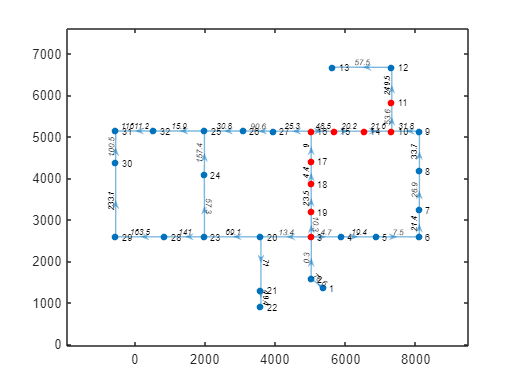

highlight(p,sp,'NodeColor','r')

## Reduced graphs (Advanced Topic) 

To reduce the number of nodes and edges, while maintaining the overall structure of the network. This will not produce a hydraulically equivalent network. It will also keep important nodes which correspond to junctions, as well as multiple paths between two nodes.

g = epanet('hanoi-3.inp');

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "hanoi-3.inp"...
Input File "hanoi-3.inp" loaded successfully.


A = g.getConnectivityMatrix

A =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1 

C = g.getNodeCoordinates;
L = g.getLinkLength;
NIP = g.getNodeNameID

NIP = 1×32 cell array
    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'10'}    {'11'}    {'12'}    {'13'}    {'14'}    {'15'}    {'16'}    {'17'}    {'18'}    {'19'}    {'20'}    {'21'}    {'22'}    {'23'}    {'24'}    {'25'}    {'26'}    {'27'}    {'28'}    {'29'}    {'30'}    {'31'}    {'32'}    {'1'}


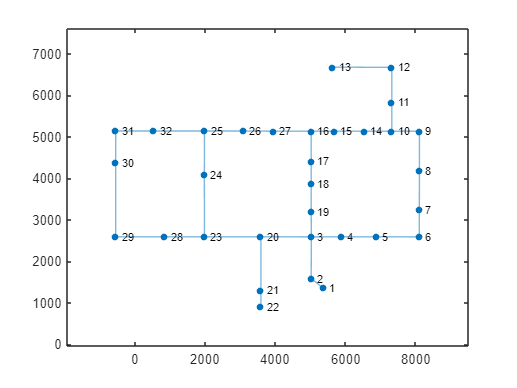

Coord = [C{1}' C{2}'];

G = graph(A);
G.Edges.Weight = L';
plot(G,'XData',Coord(:,1),'YData',Coord(:,2),'NodeLabel',NIP)

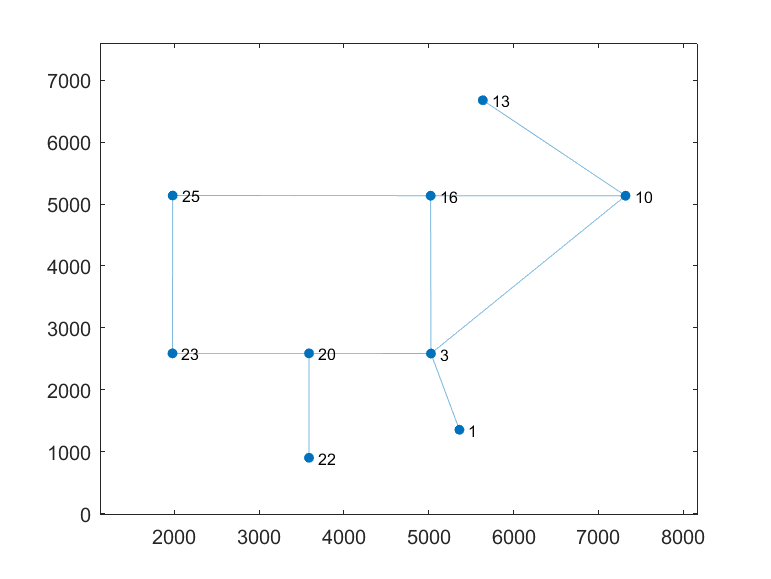


Ar = A;
%% Reduced graph - remove all in-pipe nodes
dg =  sum(Ar,2);
tmp = find( dg == 2);
while ~isempty(tmp)
    b = find(Ar(tmp(1),:) == 1);
    Ar(b(1),b(2)) = Ar(b(1),b(2)) + 1;
    Ar(b(2),b(1)) = Ar(b(2),b(1)) + 1;
    Ar(tmp(1),:) = [];
    Ar(:,tmp(1)) = [];
    Coord(tmp(1),:) = [];
    NIP(tmp(1)) = [];
    dg =  sum(Ar,2);
    tmp = find(dg == 2);
end

figure
plot(graph(Ar),'XData',Coord(:,1),'YData',Coord(:,2),'NodeLabel',NIP)

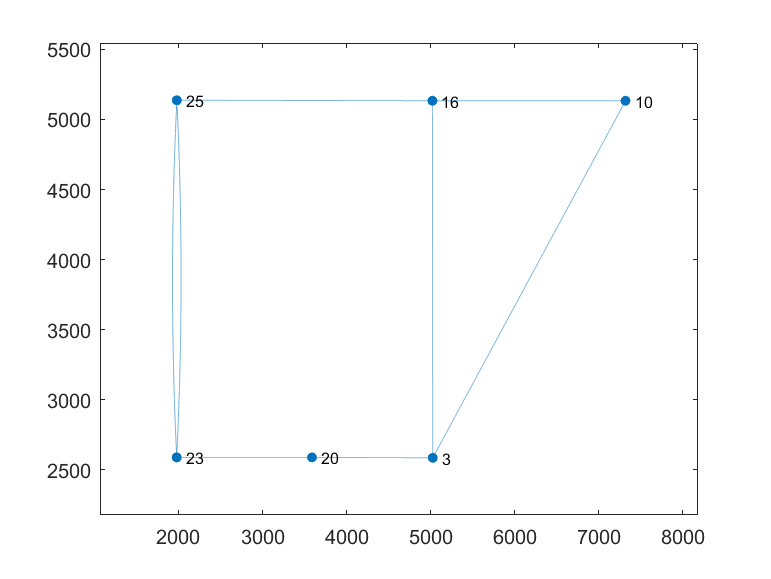


%% Reduced graph - remove all edge nodes
dg = sum(Ar,2);
tmp = find(dg == 1);
eb = 0; % number of branched edges
while ~isempty(tmp)
    eb = eb + 1;
    b = find(Ar(tmp(1),:) == 1);
    Ar(tmp(1),b(1)) = Ar(tmp(1),b(1)) + 1;
    Ar(tmp(1),:) = [];
    Ar(:,tmp(1)) = [];
    Coord(tmp(1),:) = [];
    NIP(tmp(1)) = [];
    dg = sum(Ar,2);
    tmp = find(dg == 1);
end

%% Create multigraph
s = []; t = [];
for i = 1:size(Ar,1)
    tmp = find(Ar(i,1:i) > 0);
    for j = 1:size(tmp,2)
        for l = 1:Ar(i,tmp(j))
            s = [s; i];
            t = [t; tmp(j)];
        end
    end
end

figure
Gr = graph(s,t);
plot(Gr,'XData',Coord(:,1),'YData',Coord(:,2),'NodeLabel',NIP)

## Graph Analysis

We can compare various graph networks using suitable graph metrics.

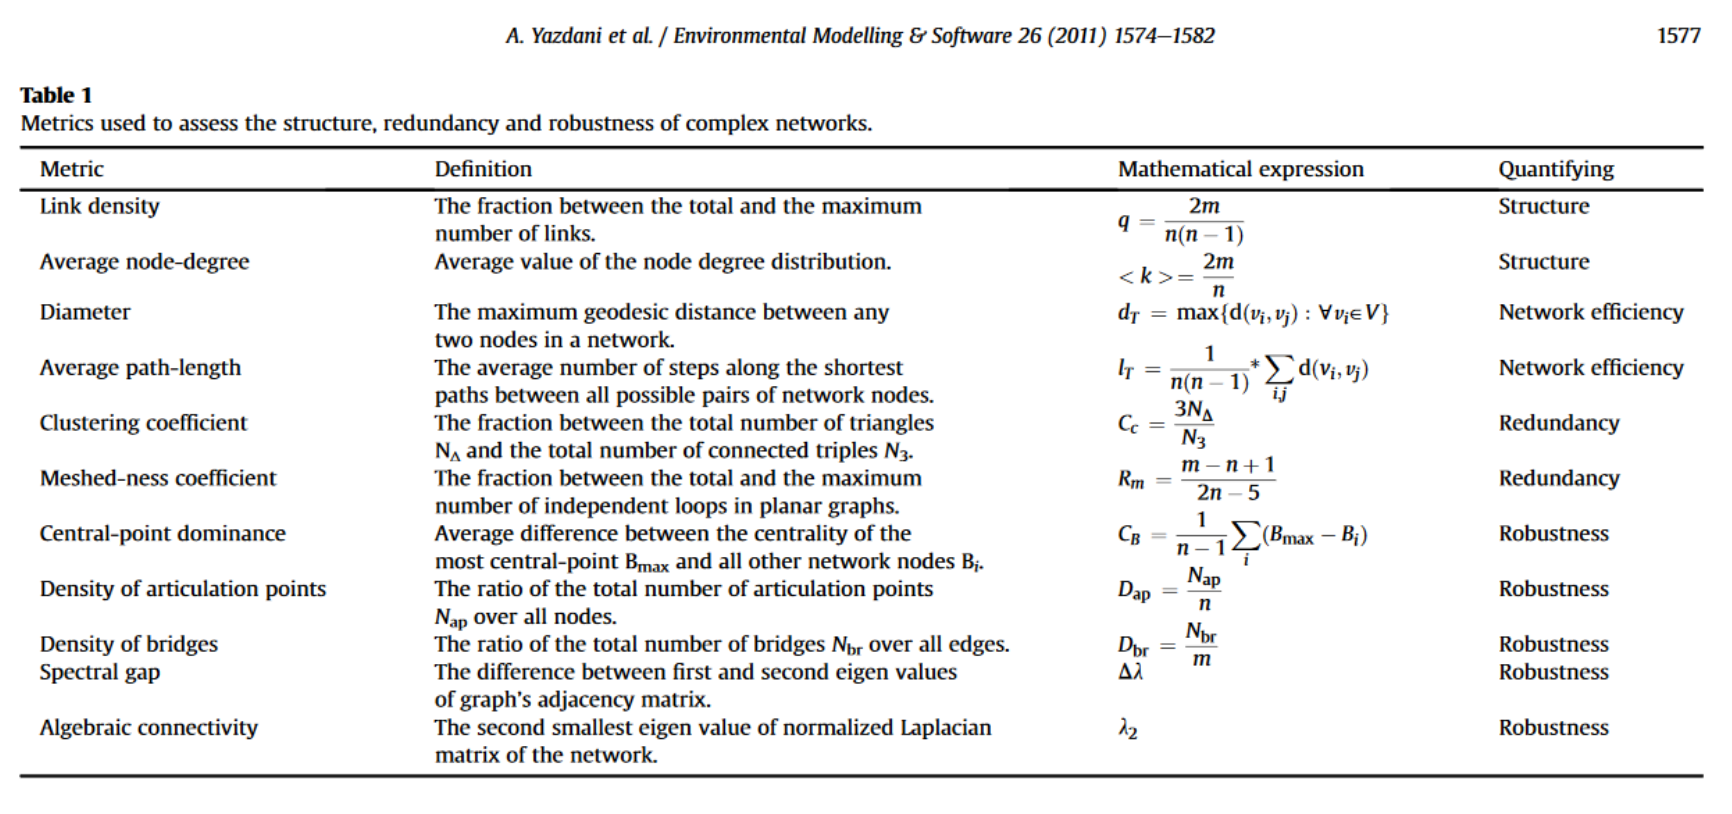

networkname = {'KY2', 'KY4', 'KY6', 'KY8','KY10', 'KY12'};
Nnets = size(networkname,2);
clear A
clear G
for i = 1:Nnets
    g = epanet([networkname{i},'.inp'], 'loadfile');
    A{i} = g.getConnectivityMatrix;
    C = g.getNodeCoordinates;
    L = g.getLinkLength;                
    NIP = g.getNodeNameID;
    Coord = [C{1}' C{2}'];
    
    G{i} = graph(A{i});
    G{i}.Nodes.X = C{1}';
    G{i}.Nodes.Y = C{2}';
end

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "KY2.inp"...
Input File "KY2.inp" loaded successfully.
EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "KY4.inp"...
Input File "KY4.inp" loaded successfully.
EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "KY6.inp"...
Input File "KY6.inp" loaded successfully.
EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "KY8.inp"...
Input File "KY8.inp" loaded successfully.
EPANET version {20200} loaded (EMT v

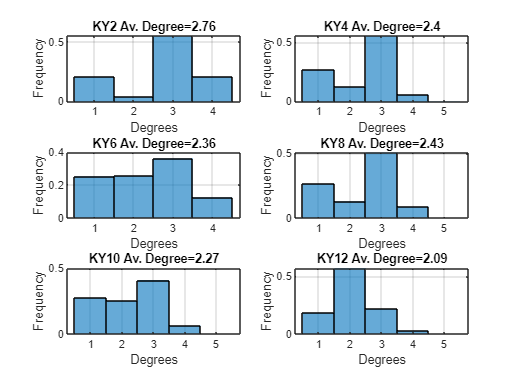


% Compare degrees
figure
for i = 1:Nnets
    dgA = degrees(A{i}); % MNT
    avdgA = mean(dgA);

    subplot(Nnets/2,2,i)
    histogram(dgA,'Normalization','probability')
    xlabel('Degrees')
    ylabel('Frequency')
    grid on
    title([networkname{i},' Av. Degree=', num2str(round(avdgA,2))])
end


% Compare Link density 
varTypes = ["string", "double", "double", "double","double","double"];
varNames = ["Network","Nodes","Edges", "Average Degree", "Link Density", "Meshedness Coefficient"];
graphMetrics = table('Size',[1,length(varNames)],'VariableTypes',varTypes,'VariableNames',varNames);

figure
for i = 1:Nnets
    e = size(G{i}.Edges,1);
    n = size(G{i}.Nodes,1);
    dgA = degrees(A{i}); % MNT
    avdgA = mean(dgA);
    LD = 2*e/(n*(n-1));
    MC = (e-n+1)/(2*n-5);
    graphMetrics(i,:) = {networkname{i}, n, e,avdgA, LD, MC };
end
% Display table
graphMetrics

graphMetrics = 6×6 table
    Network    Nodes    Edges    Average Degree    Link Density    Meshedness Coefficient
    _______    _____    _____    ______________    ____________    ______________________

    "KY2"       815     1116         2.7607          0.0033644             0.18585       
    "KY4"       964     1137         2.4025          0.0024496            0.090484       
    "KY6"       548      641         2.3613          0.0042768            0.086159       
    "KY8"      1332     1609         2.4294          0.0018151             0.10455       
    "KY10"      935     1059         2.2695          0.0024253            0.067024       
    "KY12"     2355     2452         2.0917         0.00088461            0.020829       
